# Examining the performance in a noisy environment

%% Normal environment test:
clear; close all; clc;
fprintf('For the Voice Recorded in a Normal Environment:\n');

For the Voice Recorded in a Normal Environment:


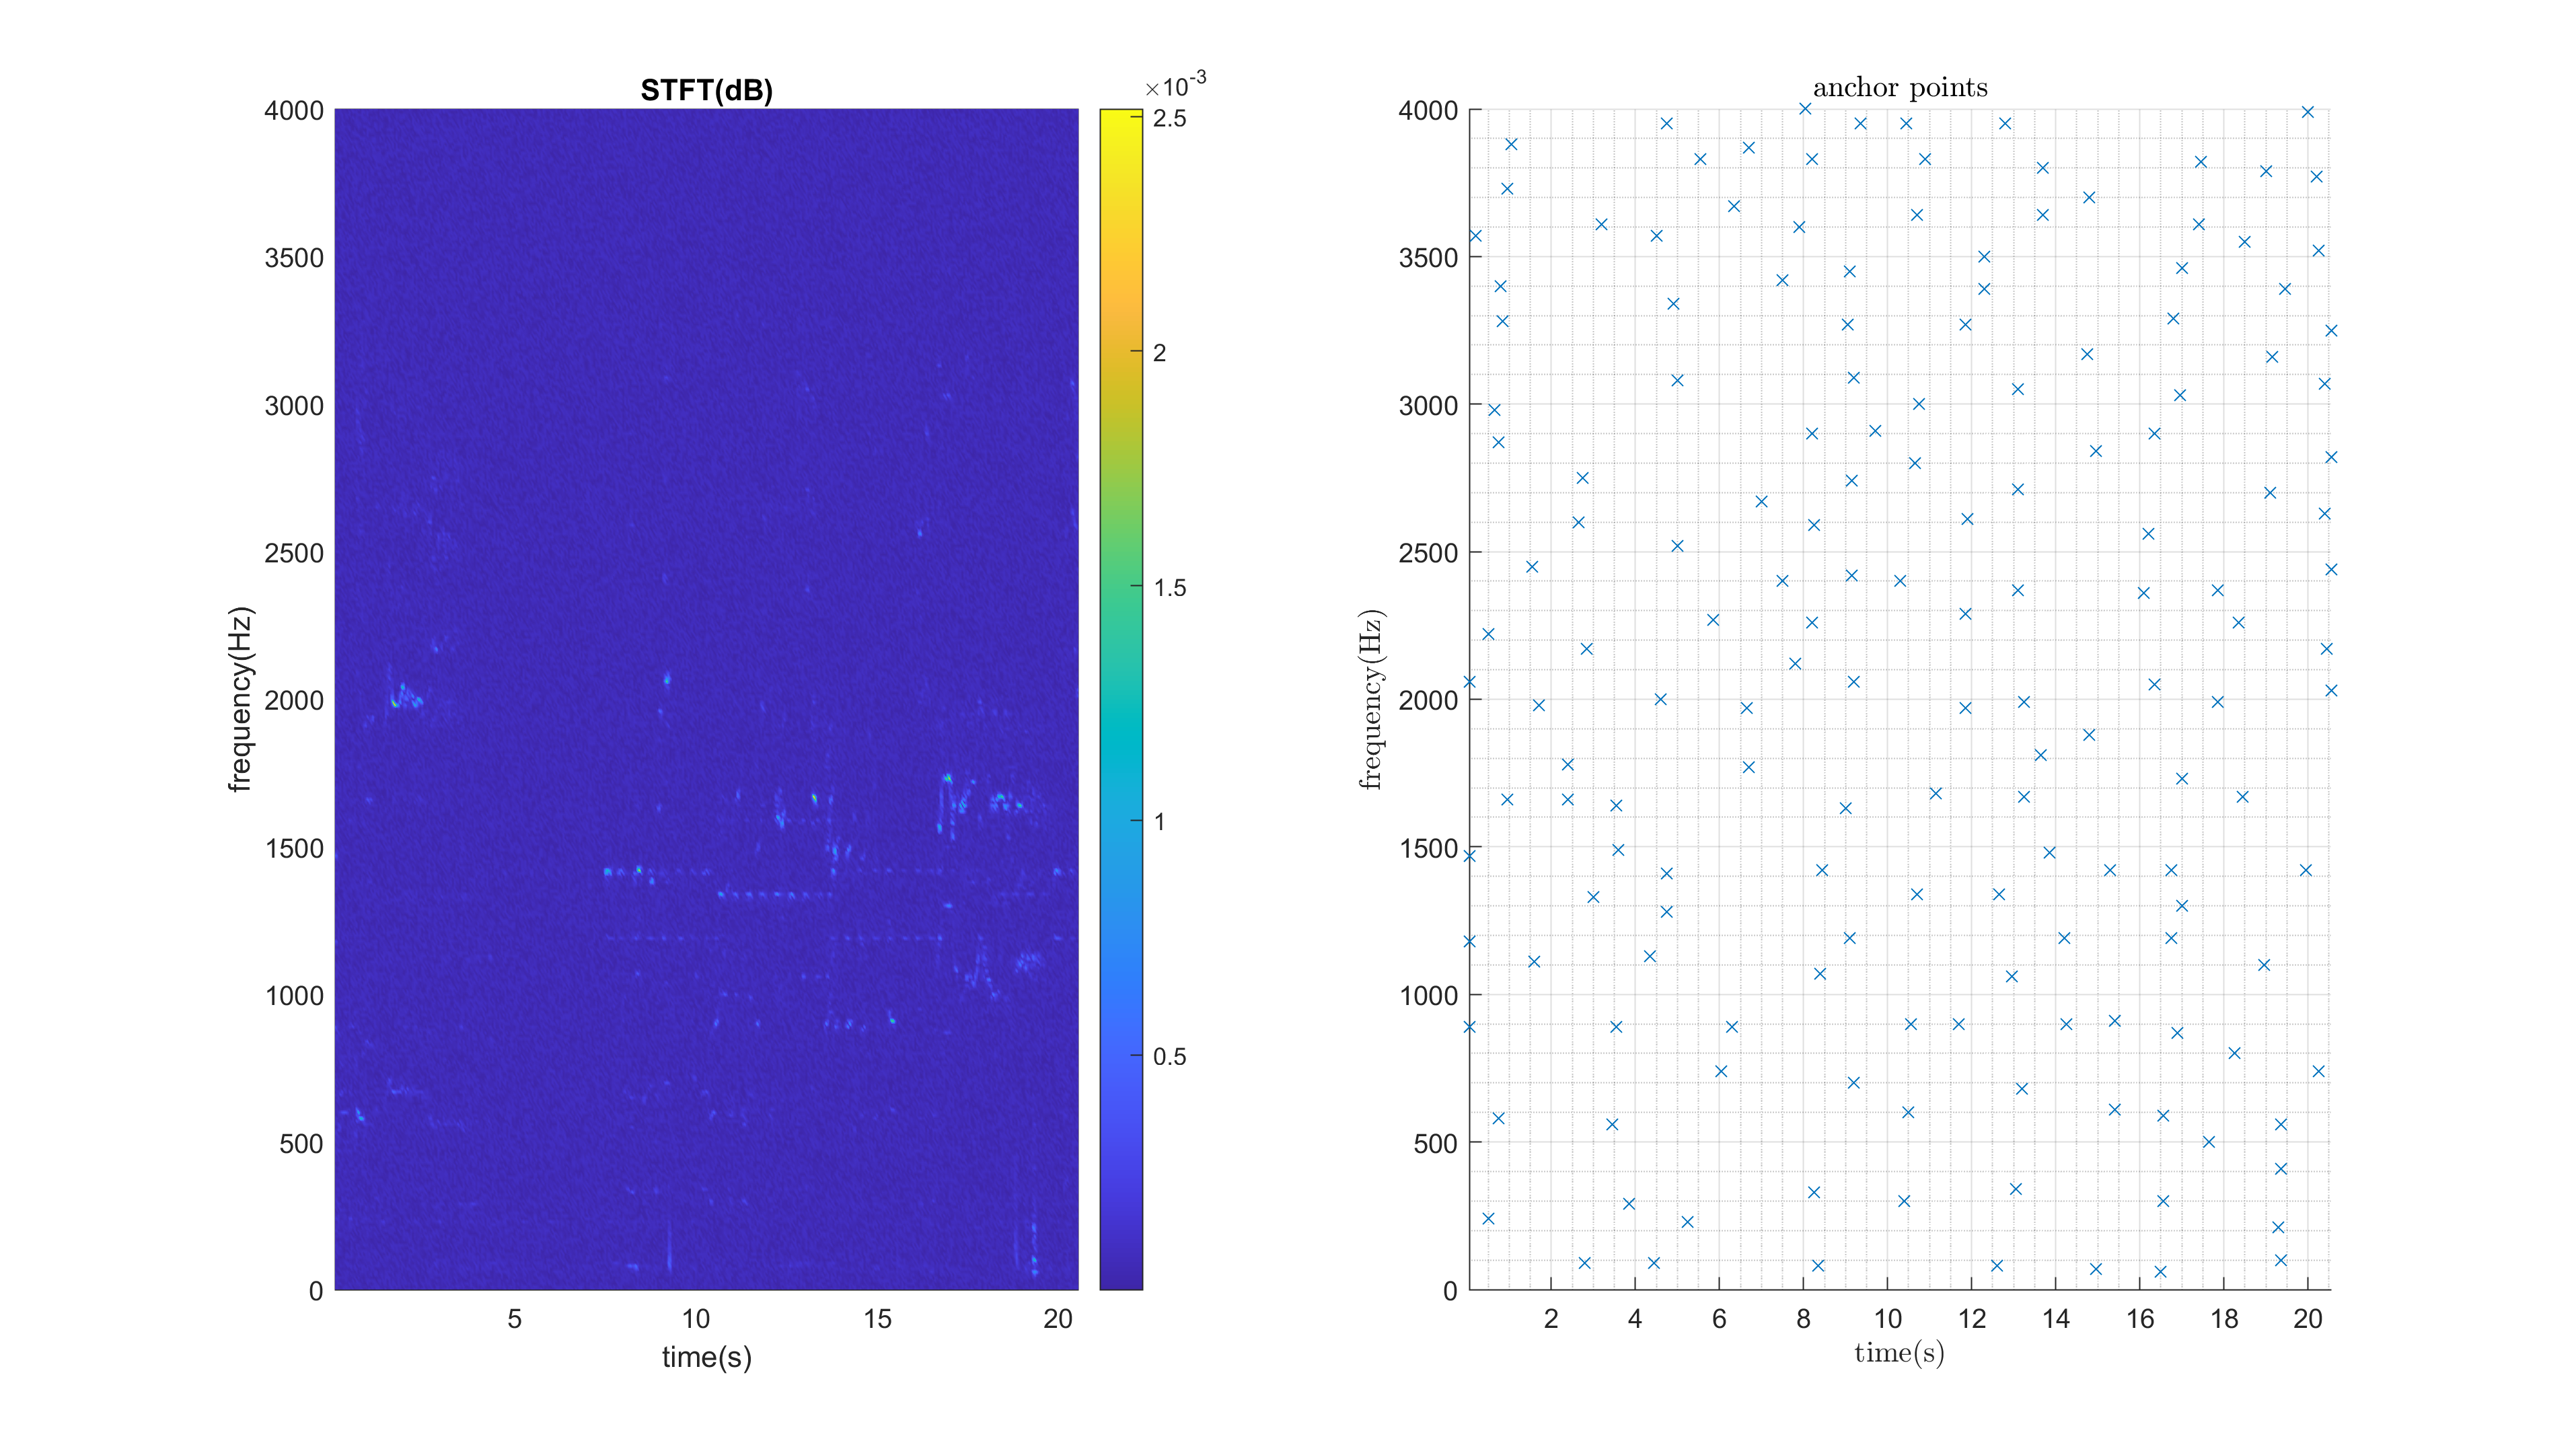

database = load('database/database.mat').database;
path = 'test_musics/'; % test musics path
song_num = 12; % music i
format = '.m4a';
[downsampled_Fs, audioMono] = import_audio(path, song_num, format);
window_time = 0.1;
[time, freq, time_freq_mat] = STFT(audioMono, downsampled_Fs, window_time);
df = floor(0.1*size(time_freq_mat, 1)/4);
dt = 2/window_time;
anchor_points = find_anchor_points(time_freq_mat, dt, df);
df_hash = floor(0.1*size(time_freq_mat,1));
dt_hash = 20/window_time;
[hash_key, hash_value] = create_hash_tags(anchor_points, df_hash, dt_hash, 0);
figure('Units','normalized','Position',[0 0 1 1])
subplot(1,2,1);
pcolor(time, freq, time_freq_mat);
shading interp
colorbar;
xlabel('time(s)');
ylabel('frequency(Hz)');
title('STFT(dB)');
df = floor(0.1*size(time_freq_mat, 1)/4);
dt = 2/window_time;
anchor_points = find_anchor_points(time_freq_mat, dt, df);
subplot(1,2,2);
scatter(time(anchor_points(:, 2)), freq(anchor_points(:, 1)),'x');
xlabel('time(s)','interpreter','latex');
ylabel('frequency(Hz)','interpreter','latex');
title("anchor points",'interpreter','latex');
xlim([time(1) time(end)]);
ylim([freq(1) freq(end)]);
grid on; grid minor;

list = []; 
for i = 1:length(hash_key)
    key_tag = [num2str(hash_key(i, 1)), '*', num2str(hash_key(i, 2)), '*', num2str(hash_key(i, 3))];
    if (isKey(database, key_tag))
        temp1 = split(database(key_tag),'+');
        for j = 1:length(temp1)
            temp2 = split(temp1{j},'*');
            list = [list; [str2num(temp2{1}),str2num(temp2{2}),hash_value(i,2)]];
        end
    end
end
scoring(list);

36 - 0.93367 - ZAZ - Je Veux
30 - 0.0057083 - Howard Shore - The Breaking of the FellowShip
49 - 0.0036093 - Salar Aghili - Che Begooyam


%% Noisy environment test:
clear;
fprintf('For the Voice Recorded in a Noisy Environment:\n');

For the Voice Recorded in a Noisy Environment:


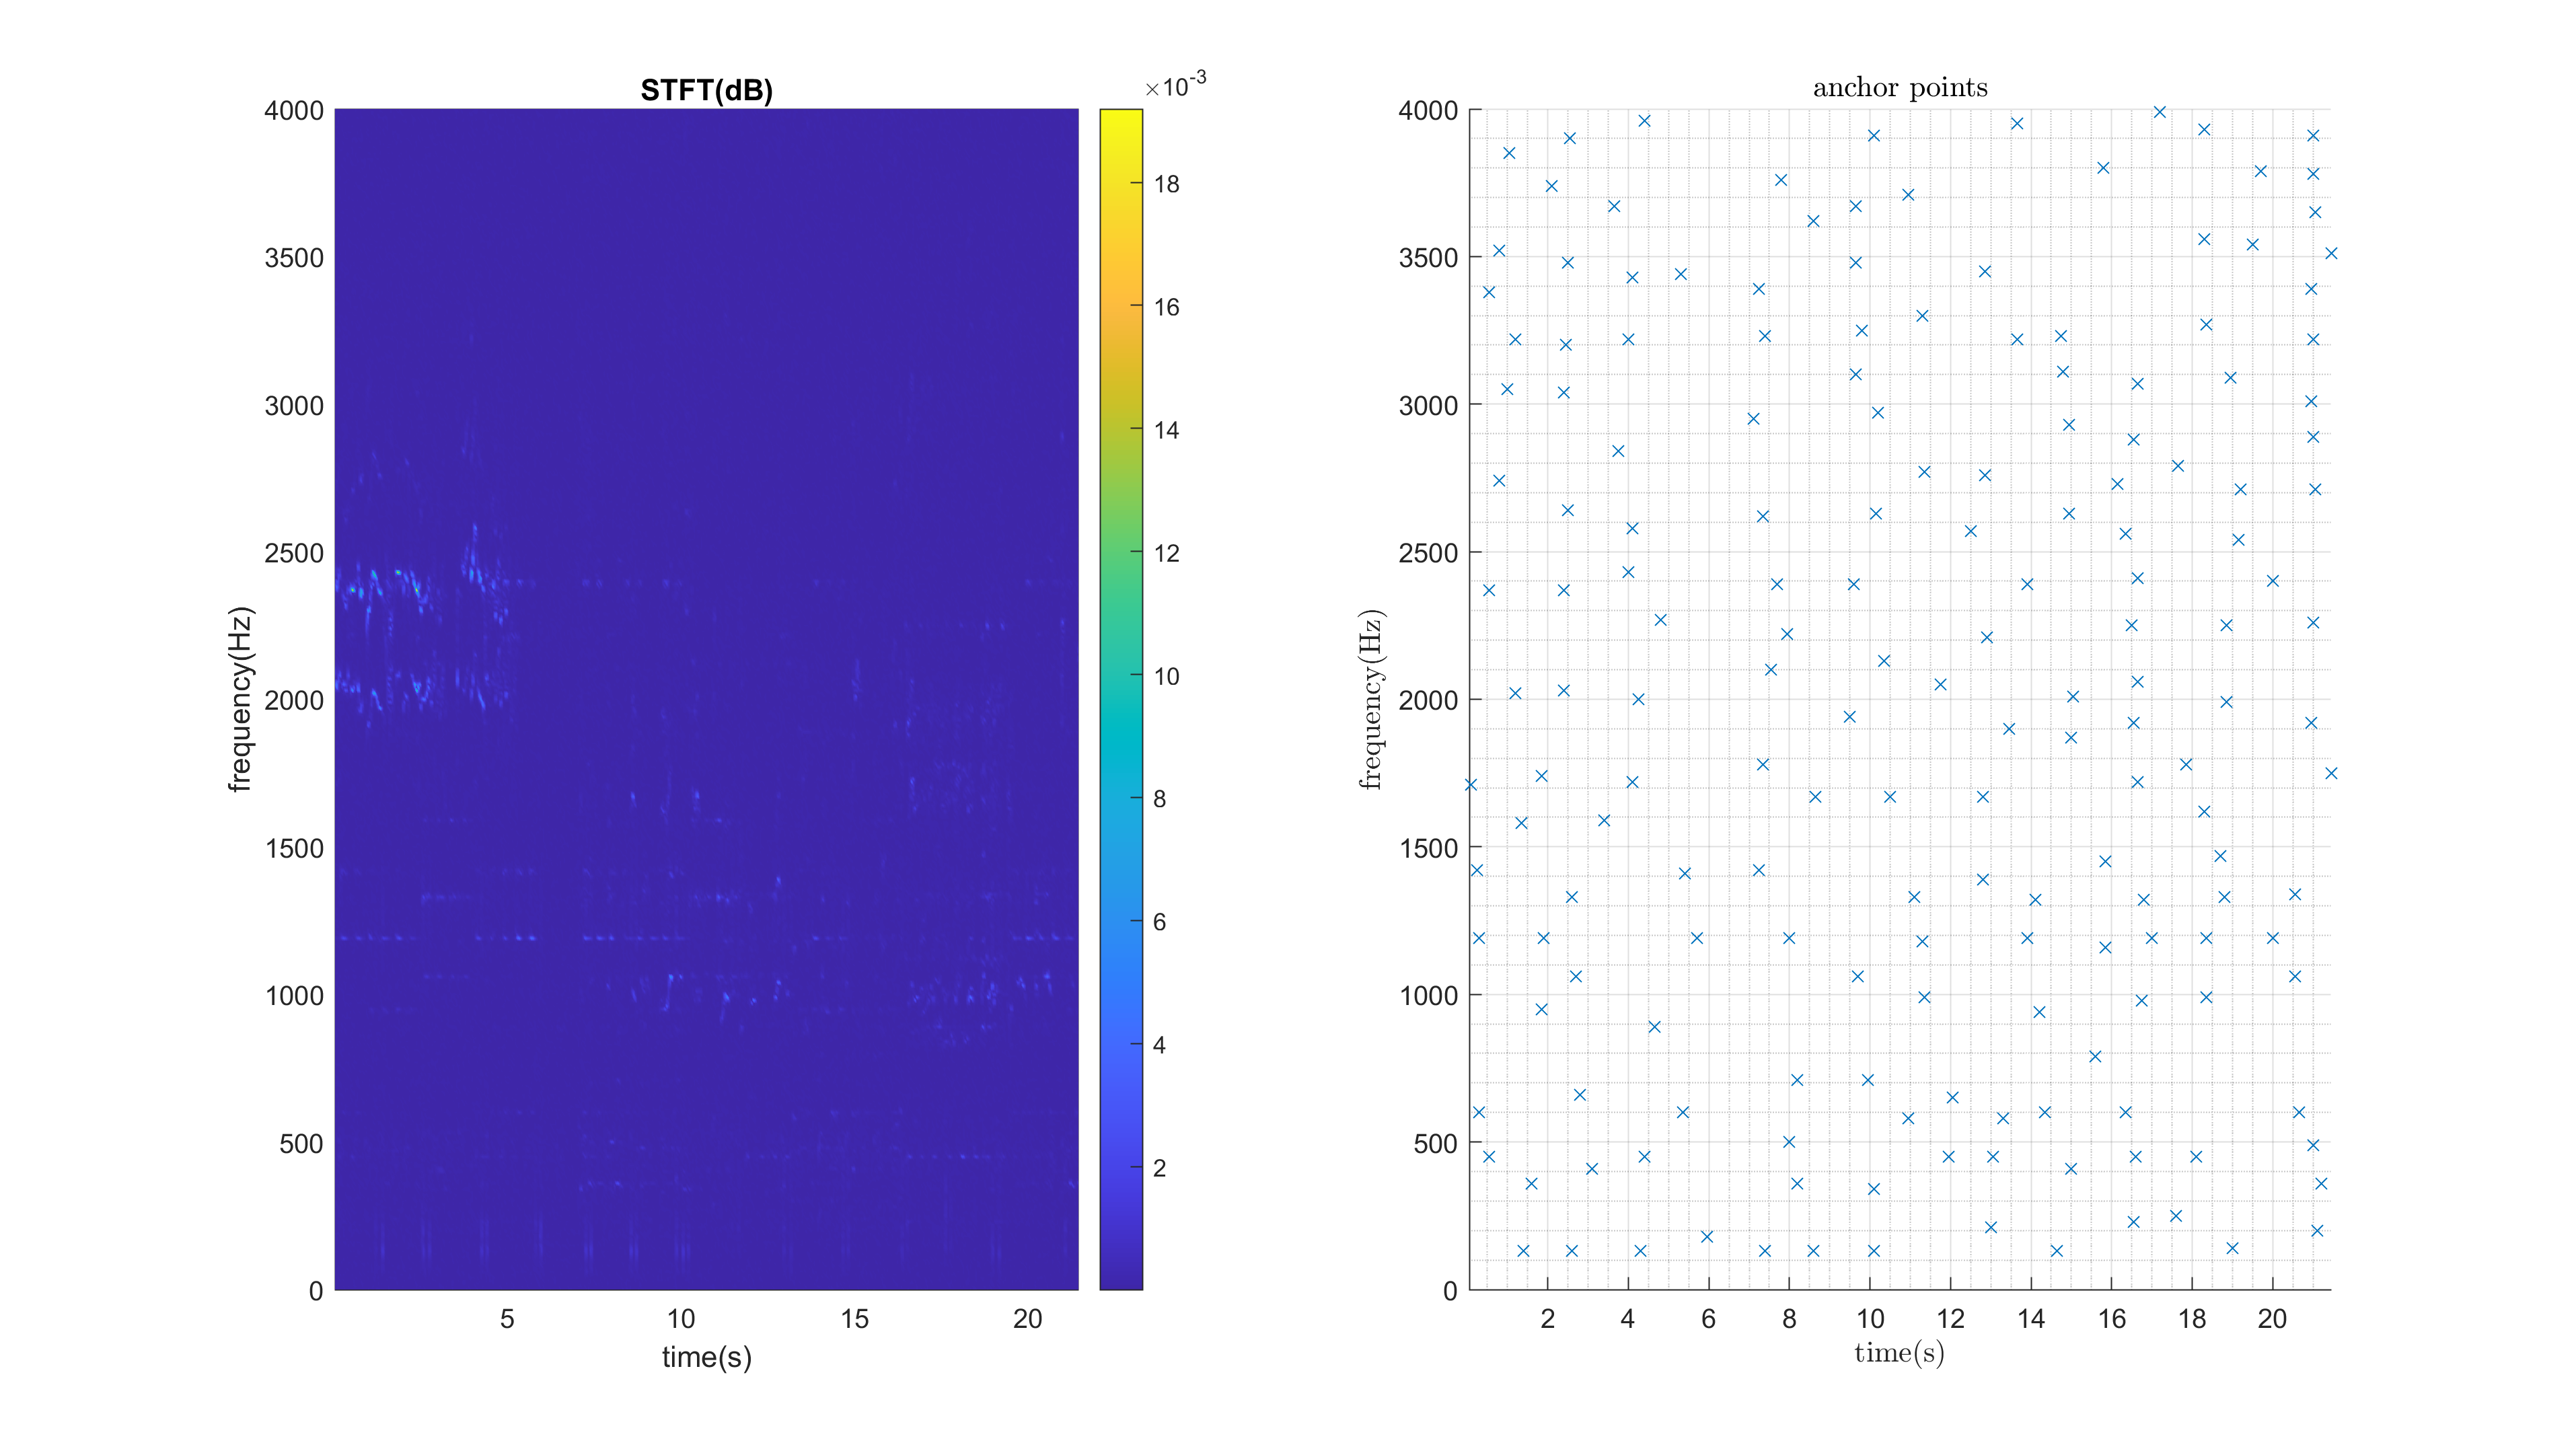

database = load('database/database.mat').database;
path = 'test_musics/'; % test musics path
song_num = 13; % music i
format = '.m4a';
[downsampled_Fs, audioMono] = import_audio(path, song_num, format);
window_time = 0.1;
[time, freq, time_freq_mat] = STFT(audioMono, downsampled_Fs, window_time);
df = floor(0.1*size(time_freq_mat, 1)/4);
dt = 2/window_time;
anchor_points = find_anchor_points(time_freq_mat, dt, df);
df_hash = floor(0.1*size(time_freq_mat,1));
dt_hash = 20/window_time;
[hash_key, hash_value] = create_hash_tags(anchor_points, df_hash, dt_hash, 0);
figure('Units','normalized','Position',[0 0 1 1])
subplot(1,2,1);
pcolor(time, freq, time_freq_mat);
shading interp
colorbar;
xlabel('time(s)');
ylabel('frequency(Hz)');
title('STFT(dB)');
df = floor(0.1*size(time_freq_mat, 1)/4);
dt = 2/window_time;
anchor_points = find_anchor_points(time_freq_mat, dt, df);
subplot(1,2,2);
scatter(time(anchor_points(:, 2)), freq(anchor_points(:, 1)),'x');
xlabel('time(s)','interpreter','latex');
ylabel('frequency(Hz)','interpreter','latex');
title("anchor points",'interpreter','latex');
xlim([time(1) time(end)]);
ylim([freq(1) freq(end)]);
grid on; grid minor;

list = []; 
for i = 1:length(hash_key)
    key_tag = [num2str(hash_key(i, 1)), '*', num2str(hash_key(i, 2)), '*', num2str(hash_key(i, 3))];
    if (isKey(database, key_tag))
        temp1 = split(database(key_tag),'+');
        for j = 1:length(temp1)
            temp2 = split(temp1{j},'*');
            list = [list; [str2num(temp2{1}),str2num(temp2{2}),hash_value(i,2)]];
        end
    end
end
scoring(list);

36 - 0.49101 - ZAZ - Je Veux
30 - 0.065631 - Howard Shore - The Breaking of the FellowShip
24 - 0.040339 - Mohsen Namjoo - Toranj


Scoring function:

function score = scoring(list)
    if ~isempty(list) % similarity length != 0
        matched_musics = unique(list(:,1)); % musics which for similarity is found
        score = zeros(length(matched_musics),2); % music name - repetition num
        eps = 0.1;
        for i = 1:length(matched_musics)
            temp = list(list(:,1) == matched_musics(i),:); 
            num = length(temp); % number of repeats for music i
            standard_dev = std(temp(:,2)-temp(:,3))/max(temp(:,2)-temp(:,3));
            score(i, 1) = matched_musics(i); % music name
            % score formula (using repetition num and std of delta ts)
            score(i, 2) = log10(num)*(1-exp((1-num)/10))*(1/(standard_dev+eps)); 
        end
        % applying softmax function to get probability distribution
        score(:, 2) = exp(score(:,2))./sum(exp(score(:,2)));
        % sorting based on scores
        [~, permutation] = sort(score(:, 2),'descend');
        score = score(permutation, :);
        songs_names = load('database/songs_names.mat').songs_names;
        %for i = 1:length(score)
        for i = 1:3
            fprintf([num2str(score(i,1)),' - ', num2str(score(i,2)),...
                ' - ', songs_names{score(i,1)}, '\n']);
        end
    else
        fprintf('list cannot be empty');
    end
end
